# Atividade 10_05

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Limiarização local (também chamada de limiarização adaptativa) baseada na média  

Uma técnica bastante difundida para limiarização adaptativa é calcular, para cada pixel, a média em uma vizinhança **sxs** e realizar seguinte operação: se o valor do pixel é t porcento menor que a média, ele é considerado ‘0’, caso contrário, é considerado ‘1’ [BR].

No MATLAB, a função que implementa essa técnica é a **adaptthresh** O parâmetro **NeighborhoodSize** atua em s e o parâmetro sensitivity em **t**.

Faça um script para testar a função **adaptthresh** nas imagens **rice.png** e **gradient_with_text.tif**. 

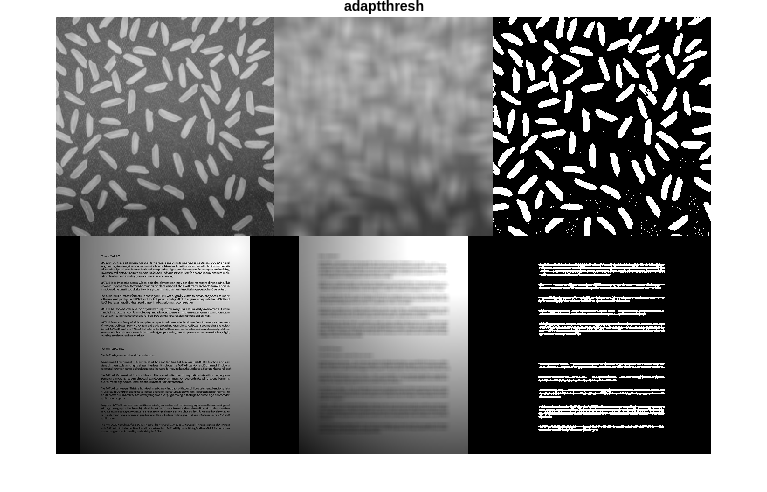

i1 = imread("rice.png");
i2 = imread("gradient_with_text.tif");

sensitivity = 0.4;
neighborhoodSize = 21;


th1 = adaptthresh(i1, sensitivity, "NeighborhoodSize", neighborhoodSize);
th2 = adaptthresh(i2, sensitivity, "NeighborhoodSize", neighborhoodSize);

bw1 = imbinarize(i1, th1);
bw2 = imbinarize(i2, th2);


figure, montage({i1, th1, bw1, i2, th2, bw2}, "Size", [2 3])
title("adaptthresh")